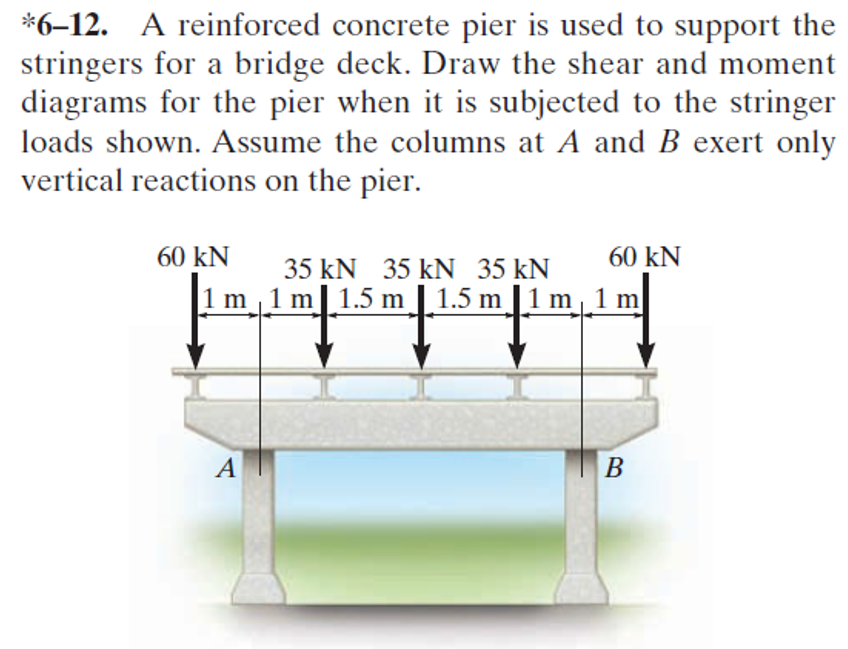

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-12P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-12P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', u.m);
b = b.add('reaction', 'force', 'Rb', 6*u.m);
b = b.add('concentrated', 'force', -60*u.kN, 0);
b = b.add('concentrated', 'force', -35*u.kN, 2*u.m);
b = b.add('concentrated', 'force', -35*u.kN, 3.5*u.m);
b = b.add('concentrated', 'force', -35*u.kN, 5*u.m);
b = b.add('concentrated', 'force', -60*u.kN, 7*u.m);
b.L = 7*u.m;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{5\,\left(x-1\,m\right)\,\left(32\,x^{2}+32\,x\,m-145\,m^{2}\right)}{16\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\leq m\\ \frac{5\,\left(x-1\,m\right)\,\left(2\,x-5\,m\right)\,\left(14\,x-41\,m\right)}{16\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(m,2\,m\right]\\ \frac{5\,\left(28\,x^{3}-204\,x^{2}\,m+399\,x\,m^{2}-167\,m^{3}\right)}{48\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(2\,m,\frac{7}{2}\,m\right]\\ -\frac{5\,\left(28\,x^{3}-384\,x^{2}\,m+1659\,x\,m^{2}-2234\,m^{3}\right)}{48\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(\frac{7}{2}\,m,5\,m\right]\\ -\frac{5\,\left(x-6\,m\right)\,\left(2\,x-9\,m\right)\,\left(14\,x-57\,m\right)}{16\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(5\,m,6\,m\right]\\ \frac{5\,\left(x-6\,m\right)\,\left(32\,x^{2}-480\,x\,m+1647\,m^{2}\right)}{16\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }6\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{15\,\left(59\,m^{2}-32\,x^{2}\right)}{16\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\leq m\\ \frac{15\,\left(28\,x^{2}-120\,x\,m+119\,m^{2}\right)}{16\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(m,2\,m\right]\\ \frac{5\,\left(2\,x-7\,m\right)\,\left(14\,x-19\,m\right)}{16\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(2\,m,\frac{7}{2}\,m\right]\\ -\frac{5\,\left(2\,x-7\,m\right)\,\left(14\,x-79\,m\right)}{16\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(\frac{7}{2}\,m,5\,m\right]\\ -\frac{15\,\left(28\,x^{2}-272\,x\,m+651\,m^{2}\right)}{16\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(5\,m,6\,m\right]\\ \frac{15\,\left(32\,x^{2}-448\,x\,m+1509\,m^{2}\right)}{16\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }6\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -60\,x\,\mathrm{kN} & \text{ if }x\leq m\\ \frac{15\,\left(7\,x-15\,m\right)}{2}\,\mathrm{kN} & \text{ if }x\in \left(m,2\,m\right]\\ \frac{5\,\left(7\,x-17\,m\right)}{2}\,\mathrm{kN} & \text{ if }x\in \left(2\,m,\frac{7}{2}\,m\right]\\ -\frac{5\,\left(7\,x-32\,m\right)}{2}\,\mathrm{kN} & \text{ if }x\in \left(\frac{7}{2}\,m,5\,m\right]\\ -\frac{15\,\left(7\,x-34\,m\right)}{2}\,\mathrm{kN} & \text{ if }x\in \left(5\,m,6\,m\right]\\ 60\,\left(x-7\,m\right)\,\mathrm{kN} & \text{ if }6\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -60\,\mathrm{kN} & \text{ if }x\leq m\\ \frac{105}{2}\,\mathrm{kN} & \text{ if }x\in \left(m,2\,m\right]\\ \frac{35}{2}\,\mathrm{kN} & \text{ if }x\in \left(2\,m,\frac{7}{2}\,m\right]\\ -\frac{35}{2}\,\mathrm{kN} & \text{ if }x\in \left(\frac{7}{2}\,m,5\,m\right]\\ -\frac{105}{2}\,\mathrm{kN} & \text{ if }x\in \left(5\,m,6\,m\right]\\ 60\,\mathrm{kN} & \text{ if }6\,m<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 112.5\,\mathrm{kN}\\ \mathrm{Rb} & 112.5\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

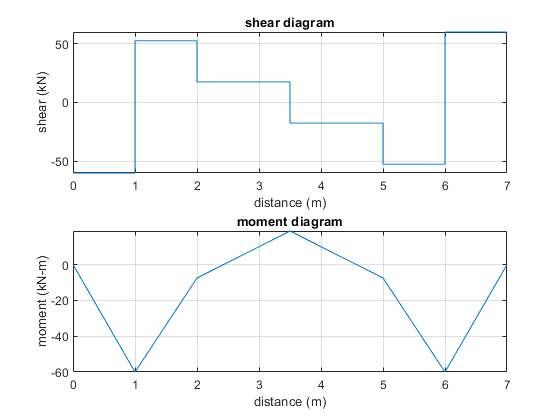

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;